# HeatmapRegionExtraction.mlx

% ============================================================

%  Copyright © 2023-2025 Xiaofeng Dai (xiaofend@umich.edu)

%  SPDX-License-Identifier: GPL-3.0-or-later

%

%  This program is free software: you can redistribute it and/or modify

%  it under the terms of the GNU General Public License as published by

%  the Free Software Foundation, either version 3 of the License, or

%  (at your option) any later version.

%

%  This program is distributed in the hope that it will be useful,

%  but WITHOUT ANY WARRANTY; without even the implied warranty of

%  MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the

%  GNU General Public License for more details.

%

%  You should have received a copy of the GNU General Public License

%  along with this program (LICENSE file in the repository root).

%  If not, see <https://www.gnu.org/licenses/>.

%

%  Tested with: MATLAB R2024a and R2022a

% ============================================================

### EXTRACTING HOT REGIONS FROM  HEAT MAP

% ------------------------------------------------------------

% Script workflow:

%   1. Reconstruct a 2‑D histogram (heatmap) from

%      the symmetrized localization list `Result_cat_sym`.

%   2. Interpolate the coarse heatmap onto a finer grid to improve

%      region boundary resolution ('cubic', 10× scaling by default).

%   3. Select a "hot" region that contains a predefined integral

%      probability mass (25 % by default).

%   4. Visualize the selected macrodomain, overlay its boundary on the

%      original heatmap.

%   5. Helper functions:

%        `Get_bincenter` — convert bin edges to bin centres.

%        `Get_HotRegion` — return pixels from hot region and

%                            the percentile‑of‑max threshold.

%        `Get_boundary`  — find boundary of the selected region.

% -------------------------------------------------------------------------

### Rebuild raw 2‑D histogram

Make sure these varables are loaded 

*'gap_y gap_x Result_cat_sym aspt_ratio low_bd up_bd'*

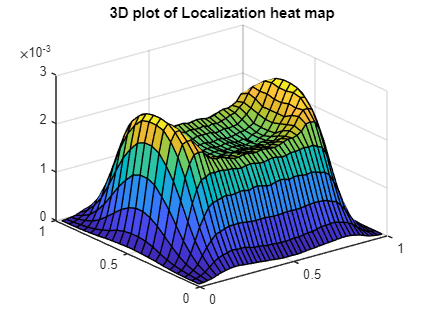

clearvars -except gap_y gap_x Result_cat_sym aspt_ratio low_bd up_bd

% get the information from 2D heatmap image
heatmap_raw = histcounts2(Result_cat_sym(:,1),Result_cat_sym(:,2),'XBinEdges',-0.5:gap_x:0.5,'YBinEdges',-0.5:gap_y:0.5,...
    'Normalization','probability');
heatmap_raw = heatmap_raw';

x = (0:gap_x:1);
x = Get_bincenter(x);

y = (0:gap_y:1);
y = Get_bincenter(y);

[X, Y] = meshgrid(x,y);
figure
surf(X,Y,heatmap_raw)
title('3D plot of Localization heat map')

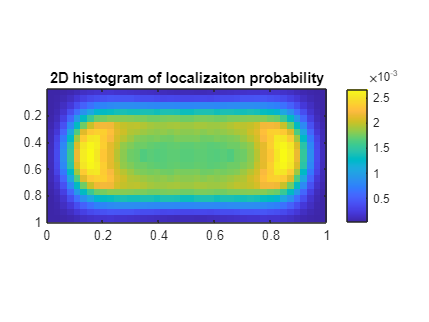


figure
imagesc(x,y,heatmap_raw)
colorbar
pbaspect([aspt_ratio 1 1])
title('2D histogram of localizaiton probability')

### Grid interpolation

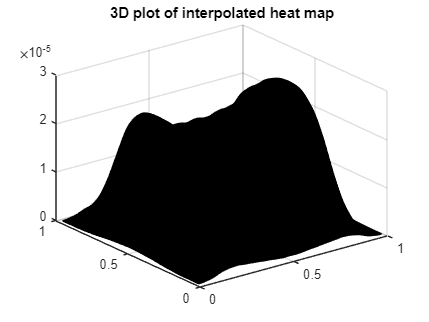

% set up scaling factor
scale_rate = 10;

xq = (0:gap_x/scale_rate:1);
xq = Get_bincenter(xq);

yq = (0:gap_y/scale_rate:1);
yq = Get_bincenter(yq);

[Xq, Yq] = meshgrid(xq,yq);
heatmap_intp = interp2(X,Y,heatmap_raw,Xq,Yq,'cubic');
heatmap_intp = heatmap_intp./(scale_rate^2);

figure
surf(Xq,Yq,heatmap_intp)
title('3D plot of interpolated heat map')

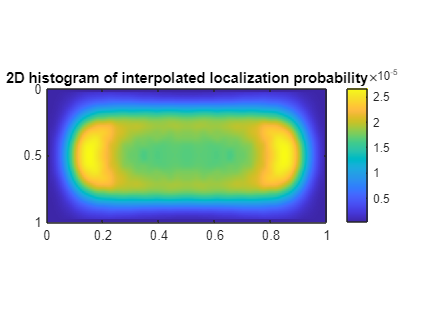


figure
imagesc(xq, yq, heatmap_intp)
colorbar
pbaspect([aspt_ratio 1 1])
title('2D histogram of interpolated localization probability')

### Extract hot region and region boundary

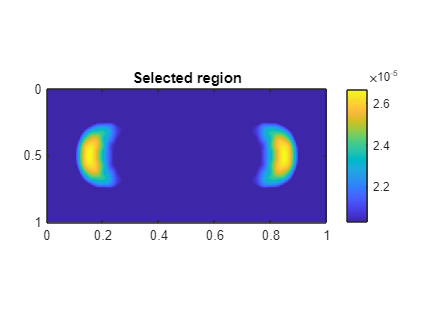

% get the hot region
[region_mac,perMax] = Get_HotRegion(heatmap_intp,0.25);

% plot the selected region 
md_region = heatmap_intp;
md_region(md_region<perMax*max(md_region,[],'all')) = NaN;
figure
imagesc(xq,yq,md_region)
colorbar
pbaspect([aspt_ratio 1 1])
title('Selected region')

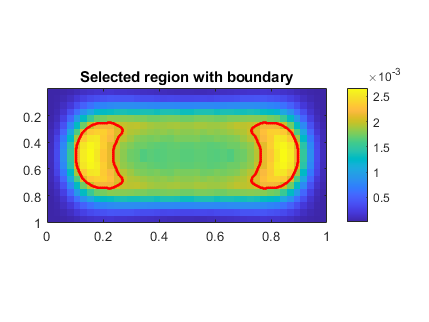


% region boundary overlaid with original heatmap
figure
imagesc(x,y,heatmap_raw)
colorbar
pbaspect([aspt_ratio 1 1])
hold on
test = Get_boundary(heatmap_intp,region_mac);
test2 = zeros(height(test),2);
for i=1:height(test)
    test2(i,1) = yq(test(i,1));
    test2(i,2) = xq(test(i,2));
end
scatter(test2(:,2),test2(:,1),4,'red','filled')
title('Selected region with boundary')

### **Helper Functions**

Get bin center from arithmetic progression array

function Bincenter = Get_bincenter(X)
    Bincenter = zeros(length(X)-1,1);
    for i=1:length(X)-1
        Bincenter(i) = 0.5*(X(i) + X(i+1));
    end 
end


Calculate nucleoid region and percentage of maximum occurancy

function [region_select, perMax] = Get_HotRegion(heatmap,thres,acc)
    if nargin==2
        acc = 1e-4;
    end
    sum_area = 0;
    cross_val = 0.5;
    cross_bd = [0,1];
    while abs(sum_area-thres)>acc
        ind = heatmap>cross_val*max(heatmap,[],'all');
        sum_area = sum(heatmap(ind));
        if abs(sum_area-thres)>acc
            if sum_area>thres
                cross_bd(1) = cross_val;
                cross_val = 0.5*(cross_val+cross_bd(2));
            else
                cross_bd(2) = cross_val;
                cross_val = 0.5*(cross_val+cross_bd(1));
            end
        end
    end
    [ind1, ind2] = find(heatmap>cross_val*max(heatmap,[],'all'));
    region_select = [ind1,ind2];
    perMax = cross_val;
end


Get boundary of selected region 

function Boundary = Get_boundary(heatmap,region_mac)
    BW = heatmap;
    for j =1:height(region_mac)
        a = region_mac(j,1);
        b = region_mac(j,2);
        BW(a,b) = 1;
    end
    BW(BW~=1) = 0;
    ind = zeros(height(region_mac),1);
    for i=1:height(region_mac)
        indr = region_mac(i,1);
        indc = region_mac(i,2);
        buff = BW(indr,indc) + BW(indr-1,indc) + BW(indr+1,indc) + BW(indr,indc-1) + BW(indr,indc+1);
        if buff<5
            ind(i) = 1;
        end
    end
    Boundary = region_mac(ind==1,:);
end